# **Visión Artificial. GIEC-GITT.**

# **Sistemas de Visión Artificial. GII-GIC-GISI.**

** Sira Palazuelos, Miguel Angel Garcia, Juan Manuel Miguel**

** Departamento de Electrónica. Universidad de Alcalá.**

**Nombre: Alejandro Fernández Ambrós, Cristina Martínez Toledo**

**Fecha:**

# Tema 4. Ejercicio 1.1. Identificación de círculos

1) Lee la imagen

RGB = imread('pillsetc.png');
imshow(RGB);

2) Umbraliza la imagen

I = rgb2gray(RGB);
bw = imbinarize(I);
imshow(bw)

3) Elimina el ruido

Usando operaciones morfológicas se eliminan los píxeles que no pertenecen a los objetos de interés.

% remove all object containing fewer than 30 pixels
bw = bwareaopen(bw,30);

% fill a gap in the pen's cap
se = strel('disk',2);
bw = imclose(bw,se);

% fill any holes, so that regionprops can be used to estimate
% the area enclosed by each of the boundaries
bw = imfill(bw,'holes');

imshow(bw)

4) Encuentra los contornos

Nos centramos sólo en los límites exteriores. La opción `'noholes' `acelerará el proceso al evitar que la función `bwboundaries` busque contornos internos. 

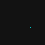

[B,L,n] = bwboundaries(bw,'noholes'); % Obtiene los contornos exteriores de los objetos y la matriz de etiquetas.

% Display the label matrix 
imshow(label2rgb(L, @jet, [.5 .5 .5]))

hold on  % to draw the next in the same figure

% draws the boundaries of each object.
for k = 1:n
  boundary = B{k};
  plot(boundary(:,2), boundary(:,1), 'w', 'LineWidth', 2)
end

Se pide:

- Utilice la ayuda de Matlab para conseguir información sobre la función `regionprops `(parámetros requeridos, propiedades que calcula, etc.).

- Usando dicha función, calcule el área y el perímetro de cada objeto de la imagen previa. 

- A partir del área y el perímetro de cada objeto devueltos por `regionprops`, calcule su circularidad mediante la expresión F=4*pi*A/(p^2) estudiada en teoría. 

- Umbralice el valor de la circularidad y resalte los objetos que sean aproximadamente circulares (p.ej., pintando las boundaries de color diferente). 

- Utilice un slider para comprobar cómo influye el valor del umbral en los objetos seleccionados. 

%% Apartado 1: ayuda de regionprops

% La función regionprops mide propiedades como el área, los centroides... de cada uno de los objetos (componentes conectados) de una imagen.
% Escribir esto en la ventana de comandos para ver la documentación: doc regionprops

% regionprops(L, 'Propiedad1', 'Propiedad2', ...) recibe una imagen binaria
% o una matriz de etiquetas y devuelve un "struct array": un elemento por
% objeto, con un campo por cada propiedad pedida (Area, Perimeter,
% Centroid, Solidity, ConvexHull, Eccentricity, BoundingBox...).




%% Apartado 2: área y perímetro de cada objeto
% Usamos L (y no bw) para que el objeto k de regionprops sea el mismo
% objeto k que el contorno B{k} de bwboundaries.
stats = regionprops(L, 'Area', 'Perimeter', 'Centroid');

% [stats.Area] junta en un vector el campo Area de todos los objetos
areas = [stats.Area]; % número de píxeles del objeto.
perimetros = [stats.Perimeter]; % longitud del contorno.




%% Apartado 3: circularidad F = 4*pi*A / p^2
% Los operadores con punto (./  .^) operan elemento a elemento,
% es decir, calculan F para cada objeto a la vez.
F = 4*pi*areas ./ (perimetros.^2);

% Muestro una tabla con los resultados (el ' convierte fila en columna)
tablaCirc = table((1:n)', areas', perimetros', F', ...
    'VariableNames', {'Objeto', 'Area', 'Perimetro', 'Circularidad'})




%% Apartados 4 y 5: umbral de circularidad (con slider)
umbralF = 0.85;   % <-- AQUÍ VA EL SLIDER (ver explicación abajo)

figure
imshow(RGB)       % imagen original de fondo
hold on           % para dibujar encima sin borrarla

for k = 1:n
    boundary = B{k}; % contorno del objeto k [fila, col]
    if F(k) >= umbralF
        colorBorde = 'g'; % verde: objeto circular
    else
        colorBorde = 'r'; % rojo: objeto no circular
    end
    plot(boundary(:,2), boundary(:,1), colorBorde, 'LineWidth', 2)

    % Escribo el valor de F en el centro de cada objeto
    c = stats(k).Centroid;              % centroide [x, y]
    text(c(1), c(2), sprintf('%.2f', F(k)), 'Color', 'y', ...
        'FontWeight', 'bold', 'HorizontalAlignment', 'center')
end

hold off
title(['Verde: circularidad >= ', num2str(umbralF)])

# Tema 4. Ejercicio 1.2. Identificación de objetos cóncavos/convexos

- Cargue la imagen `'Figure1.jpg'` 

- Utilice la función `regionprops` para calcular el área, el área convexa y el índice de convexidad (Solidity). Visualice una tabla con las tres propiedades para todos los objetos de la imagen.

- Resalte la envolvente convexa ('ConvexHull') de cada objeto: en blanco para los objetos cóncavos y en magenta para los convexos, utilizando el valor de `Solidity` para diferenciarlos.

- Utilice un slider para umbralizar el índice de convexidad dentro del rango de valores obtenido (según aparecen en la tabla del punto 2) y compruebe qué objetos son seleccionados al variar el valor del umbral. Justifique si la selección es correcta según los valores obtenidos. 

%% Ejercicio 1.2 - Apartado 1: cargar la imagen
RGB2 = imread('Figure1.jpg');
I2   = rgb2gray(RGB2);

% En esta imagen los objetos son NEGROS sobre fondo BLANCO.
% imbinarize daría el fondo como 1, así que invierto con ~ (NOT lógico)
bw2 = ~imbinarize(I2);
bw2 = bwareaopen(bw2, 50);       % quita puntitos de ruido del JPG
bw2 = imfill(bw2, 'holes');      % rellena posibles agujeros

L2 = bwlabel(bw2);               % etiqueta los objetos: 1, 2, 3...
numObj = max(L2(:));             % número de objetos

%% Apartado 2: área, área convexa y Solidity
stats2 = regionprops(L2, 'Area', 'ConvexArea', 'Solidity', ...
    'ConvexHull', 'Centroid');

tablaConv = table((1:numObj)', [stats2.Area]', [stats2.ConvexArea]', ...
    [stats2.Solidity]', ...
    'VariableNames', {'Objeto', 'Area', 'AreaConvexa', 'Solidity'})
% Puedes comprobar que Solidity = Area ./ AreaConvexa

%% Apartados 3 y 4: envolvente convexa coloreada según Solidity (slider)
umbralS = 0.95;   % <-- AQUÍ VA EL SLIDER (mín 0.7, máx 1, paso 0.01)

figure
% Fondo gris y objetos de colores, para que se vea el contorno blanco
imshow(label2rgb(L2, @jet, [.5 .5 .5]))
hold on

for k = 1:numObj
    hull = stats2(k).ConvexHull;   % vértices de la envolvente
    % OJO: ConvexHull viene como [x, y] (columna, fila), al revés que
    % bwboundaries. Por eso aquí es hull(:,1), hull(:,2)
    if stats2(k).Solidity >= umbralS
        colorHull = 'm';           % magenta: convexo
    else
        colorHull = 'w';           % blanco: cóncavo
    end
    plot(hull(:,1), hull(:,2), colorHull, 'LineWidth', 2)

    % Número del objeto, para poder relacionarlo con la tabla
    c = stats2(k).Centroid;
    text(c(1), c(2), num2str(k), 'Color', 'k', 'FontWeight', 'bold', ...
        'HorizontalAlignment', 'center')
end

hold off
title(['Magenta: convexo (Solidity >= ', num2str(umbralS), ')  Blanco: cóncavo'])